Kathia Coronado

Febuary 8, 2019

RBE 500

Dr. Hata

# **Week 1 Assignment**- Intro to Matlab and Simulink

## Problem:

The sinusoidal function, g(t), increases linearly in frequency from 0 Hz at t =0 seconds to 5 Hz at t=10 seconds. Plot the graph of this function using MATLAB's plot command and write a high-quality report. 

### Introduction and Literature Review:

Sinusoidal waves are one of the most used waveforms, as they often produce a good approximation for signals that occur in nature. Waves such as sound, wind and light can often be approximated by sine waves (3). These wave forms can only be approximated as no wave is completely periodic. Sinusoidal waves describe smooth repetitive oscillations. **Figure 1** displays the plot of a sine wave. 

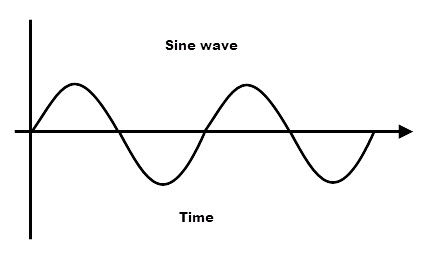

**Figure 1 **Plot of a sinusoidal wave as a function of time (3).

### Methods:

The equation for a sine wave as a function of time is displayed in equation 1. Here A is the amplitude, f is the frequency, and *φ* is phase. Frequency describes the number of times a periodic even occurs per unit of time. Phase is the horizontal shift of a sinusoidal function. The period of a wave can be calculated by inverting the frequency, see equation 2. Equation 3 displays how angular frequency, *ω*, can be calculated to further reduce equation 1. Angular frequency describes the change in angle over time, therefore equation 4 can be used to further simplify equation 1. 

$y\left(t\right)=A\;\sin \;\left(2\pi \textrm{ft}+\varphi \right)=A\;\sin \left(\omega t+\varphi \right)=A\;\sin \left(\theta \left(t\right)+\varphi \right)=A\;\sin \;\left(\varphi \left(t\right)+\varphi \right)\;$        (1)

$T=\frac{1}{f}$                                                                                                                        (2)

$\omega =\frac{2\pi }{T}=2\pi f$                                                                                                            (3)

$\theta \left(t\right)=\omega t$                                                                                                                   (4)

Waves that have frequencies that either increase, up-chirp, or decrease, down-chirp, with time are described as chirp or sweep signals (1). These types of waves are commonly seen in radar, sonar, and laser systems (2). Linear chirps, have frequencies that vary linearly with time, see equation 5. In this equation *c* is the chirp rate and  is the starting frequency at time zero. The chirp rate is calculated by taking the difference between the ending, , and starting,, frequencies and then dividing the difference by the time elapsed,, shown in equation 6. The time dependent periodic phase function of a periodic function is calculated by taking the integral of the time dependent frequency function f(t), see equation 7. To calculate the time dependent equation of a sinusoidal linear chirp wave, equation 8, equation 7 is plugged into equation 1. 

$f\left(t\right)=\textrm{ct}+f_0$                                                                                                               (5)

$c=\frac{f_1 -f_0 }{\Delta t}$                                                                                                                     (6)

$\phi \left(t\right)=\phi_0 +2\pi \int_{t_0 }^{t_1 } f\left(\tau \right)d\tau =\phi_0 +2\pi \int_{t_0 }^{t_1 } \left(\mathrm{c}\tau +f_0 \right)d\tau =\phi_0 +2\pi \left(\frac{c}{2}t^2 +f_{0\;} t\right)\;\;\;\;$                (7)

$y\left(t\right)=A\;\sin \left\lbrack \phi_0 +2\pi \left(\frac{c}{2}t^2 +f_{0\;} t\right)\right\rbrack$                                                                                (8)

Chirp signals have varying frequencies as a function of time. To calculate the instantaneous frequency of a linear chirp wave, the derivative of the argument inside of the sine function, in equation 8, must be calculated. This derivative is then divided by  to get the frequency in hertz, see equation 9.

$f_i \left(t\right)=\frac{1}{2\pi }\frac{d\left(\phi_0 +2\pi \left(\frac{c}{2}t^2 +f_{0\;} t\right)\right)}{d\;t}$                                                                                (9)

A function, g(t), that increases linearly in frequency for 0 Hz at t =0 seconds to 5 Hz at t =10 seconds, can be described as an up-chirp sinusoidal signal. First the chirp rate of the function was calculated using equation 6.  Here   is 5 Hz,  is 0 Hz and  is 10 seconds. The time dependent frequency of the function was then calculated using equation 5. For this assignment, it was assumed that  the amplitude, A, was 1 and the at the initial phase shift, , is 0. Equation 8 was then utilized to obtain the function g(t).

Using equation 9, the instantaneous frequency for g(t) was calculated. This equation can be used to calculate the frequency of the function at any time, t.

To plot the chirped sinusoidal function, g(t), at a constant sample rate of  5 Hz, equation 2 was used. This calculated the period needed to sample at 5 Hz. This period was then used as the time increment for plotting the function from t=0 seconds to t =10 seconds. 

### Results : 

#### Part 1:

The equation of g(t):


$$g\left(t\right)=\mathrm{sin}\left\lbrack \frac{1}{2}\pi t^2 \right\rbrack \;\;\;\;\;\;\;\;\;\;\;$$


The equation for the instantaneous frequency of g(t) :


$$f_i \left(t\right)=\frac{1}{2}t$$


syms t;
f0=0; t0=0;
f1= 5; t1=10;
phase0= 0;
A=1;

c= (f1-f0)/(t1-t0);
g= A*sin(phase0+2*pi*(c/2*t.^2+f0*t))  

$$g = \sin\left(\frac{\pi \,t^{2}}{2}\right)$$


fi= t/2;

fa=2;
fb=3; 
fc=4.8;
fd=5;

ta = 2*fa;
tb = 2*fb;
tc = 2*fc
td = 2*fd

#### Part 2:

MATLAB’s plot function was used to plot the up-chirp Sinusoidal function with respect to time from t=0 to t=10.

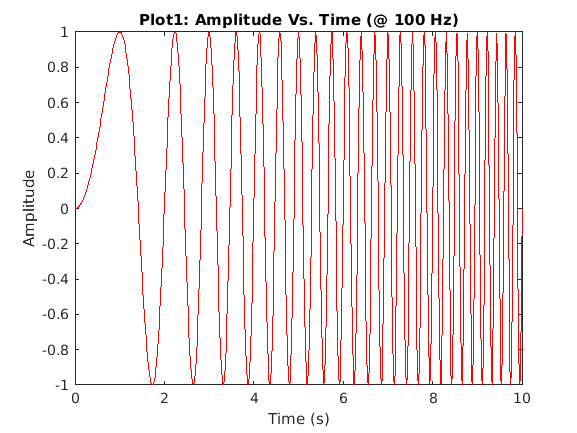

figure(1);
t1 = 0:0.01:10;
g1= sin(0.5*pi*t1.^2);
plot(t1, g1, "Color",[1,0,0]);

title('Plot1: Amplitude Vs. Time (@ 100 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');

#### Part 3:

To plot g(t) at a continuous sample of frequency of 5 Hz, the given frequency was inverted to calulate a period. This period was then used as the rate by which the the function was plotted from 0 to 10 seconds. MATLAB’s plot function was used again to plot the function g(t), at the a continuous sampling frequency of 5 Hz. 

figure(2);

T= 1/5;
t2= 0:T:10;
g2= sin(0.5*pi*t2.^2);

plot(t2, g2, "Color",[0.7,0,1]);
title('Plot 2: Amplitude Vs. Time @ (5 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');

MATLAB’s plot function was used to plot the plot 1 and plot 2 on the sample graph

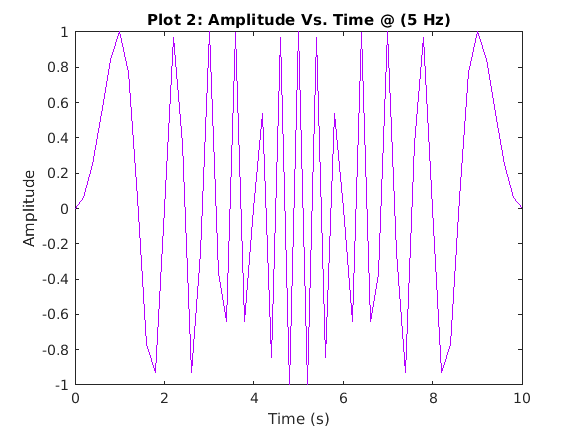

figure(3);



plot(t1,g1,t2,g2);
title('Plot 3: Amplitude Vs. Time ');
xlabel('Time (s)');
ylabel('Amplitude');
legend('100 Hz sampling','5 Hz sampling');


#### Discussion:

The most challenging part of this assignment was developing the proper equation for the sine wave described by the problem statement. In my initial attempt at tackling this problem, I assumed that the function, g(t), was a constant frequency sinusoidal wave. I foolishly thought that I could take the average change in frequency over time and use that to plug into my equation. This resulted in very simple plots for the function. After revisiting the problem, a couple of days later, I realized that my assumption was incorrect and that I was not reading the problem carefully enough. Once, Identified the problem in my solution I began to research variable frequency sinusoidal waves and came across linear chirped waves. 

In the first part of the results, I calculated the equation for function g(t). The derived equation was what I expected for a sinusoidal function with a varying frequency of 0Hz to 5 Hz in 10 seconds. The chirp rate was calculated to be 0.5, this makes sense because the rate at which the frequency changes over time in the function 5Hz in 10 seconds, this reduces to 0.5 Hz per second. The function also has a  term. This term is necessary because a linear frequency chirp function, is expected to have a quadratic phase signal. 

In part 2 the results, the plot of g(t) is displayed, see plot 1. Plot 1 was plotted at a sample rate of 100 Hz.  The function starts off with a low frequency and long period, as time elapses the frequency of the function increases and as a result the period shortens. The function increases its frequency from 0 Hz to 5 Hz as it reaches 10 seconds; at 10 seconds the function is equal to 5 Hz.

During part 3 of the solution, I plotted g(t) at a continous sampling frequency of 5 Hz, see plot 2. To better compare the plots of the function at different sampling rates, I created plot 3. Plot 3 plots both plot 1 and plot 2 on the sample plot. When comparing the two plots, i noted that the function was smoother and had a higher resultion when plotted at 100 Hz, the higher frequency. When plotted at a sample rate of 5 Hz,  the function looses many of the distinctive features it has when plotted at the higher resolution. At 5 Hz, the function have very pointy peaks and it loses its incrementally increasing frequency pattern. To avoid losing an amount of data points that will cause the function to lose its distinctive features, Nyquist's sampling theorem should be used. Nyquist's sample theorem states that sampling rate should be atleast twice the maximum frequecy responses (4). In the case of the assignment problem, the maximum frequence response is 5 Hz; therefore sample at 5 Hz is too low. the function needs to be sampled at alteast 10 Hz. Plot 4, below, displays the function sampled at 10Hz.

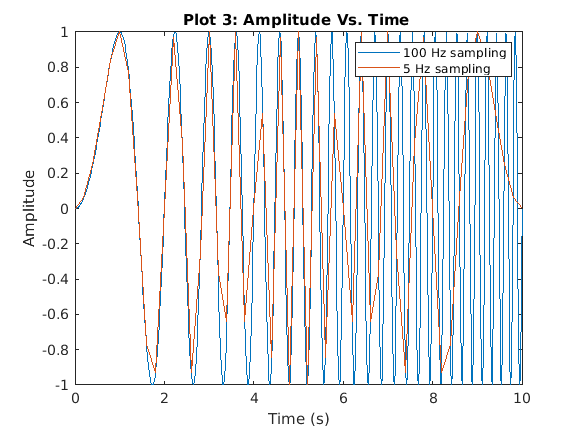

figure(4);

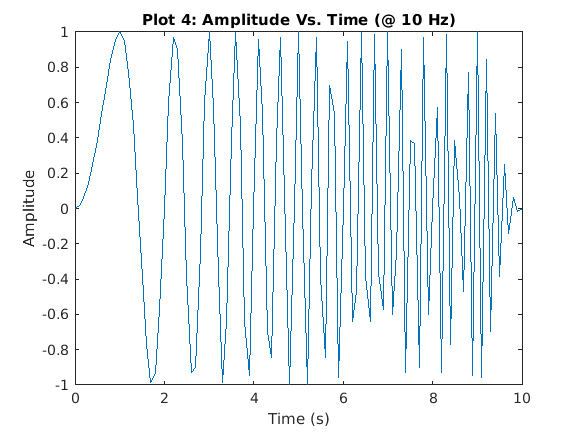


t3=  0:0.1:10;
g3=  sin(0.5*pi*t3.^2);
plot(t3,g3);
title('Plot 4: Amplitude Vs. Time (@ 10 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');

Plotting the image at 10 Hz is an improvement on the 5 Hz  plot; the changes in frequency over time of the plot are more noticeable. Despite it being an improvement it is still not great, as we loose alot of information about the actual amplitude of the wave at the higher frequences. All in all, the higher sampling rate the better the function will be represented graphically. 

### References:

(1)  McClellan, Schafer, Yoder. DSP First 2e.(2016). *Chirp Signals*. DSP First. http://dspfirst.gatech.edu/chapters/03spect/demos/spectrog/chirps/index.html

(2) Wikipedia. (2021, February 3). *Chirp*. Wikipedia. https://en.wikipedia.org/wiki/Chirp

(3) Wikipedia. (2021, February 5). *Sine Waves*. Wikipedia. https://en.wikipedia.org/wiki/Sine_wave 

(4) Marshall, Dave. (2001, October 4). *Nyquist's Sampling Theorem*. Users. https://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/node149.html

[](http://dspfirst.gatech.edu/chapters/03spect/demos/spectrog/chirps/index.html)